# PARTE 2: Laboratorio 2 MyS

- Autores: Vanina Correa y John Serrano

Se busca obtener el modelo de estado algebraico del sistema, utilizando las matrices A, B, C y D. Luego se grafica el resultado del sistema ante un impulso, un escalon y una función u(t).

% Se limpian las variables guardadas en el Workspace.
clearvars;

% Se definen las matrices A, B, C y D
A = [-15 10; 5 -7.5];
B = [0.5; 0.25];
C = [1 0; 0 1];
D = 0;

% Se obtiene el modelo de estado del sistema
H_S = ss(A,B,C,D)

H_S =
 
  A = 
         x1    x2
   x1   -15    10
   x2     5  -7.5
 
  B = 
         u1
   x1   0.5
   x2  0.25
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.
Model Properties



% Se utiliza la función mab() desarrollada en la parte 1 para
% obtener la función de transferencia H(s) del sistema.
H = mab(A,B,C,D)

H =
 
  From input to output...
         0.5 s^3 + 17.5 s^2 + 171.9 s + 390.6
   1:  ----------------------------------------
       s^4 + 45 s^3 + 631.2 s^2 + 2812 s + 3906
 
        0.25 s^3 + 11.87 s^2 + 156.2 s + 390.6
   2:  ----------------------------------------
       s^4 + 45 s^3 + 631.2 s^2 + 2812 s + 3906
 
Continuous-time transfer function.
Model Properties


Como se puede observar, se obtienen dos funciones de transferencia ya que se tienen dos salidas. Ahora es necesario definir la entrada u(t) para poder probar estas funciones de transferencia ante la entrada u(t), como también ante un escalón y un impulso.

% Se define el intervalo de tiempo a utilizar para u(t)
t = linspace(0, 12*pi, 5000);
% Se define u(t)
u = 100*sin(t/4);
u(u<0) = 0.;

Ahora solo queda realizar los gráficos correspondientes.

En primer lugar, la respuesta ante la entrada u(t) para ambas salidas.

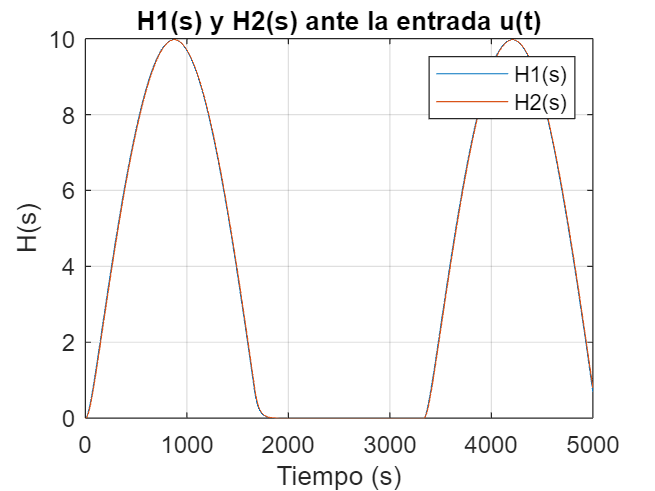

% Gráfico de H1(s) y H2(s) ante u(t)
figure;
plot(lsim(H, u, t));
title("H1(s) y H2(s) ante la entrada u(t)");
ylabel("H(s)");
xlabel("Tiempo (s)");
legend("H1(s)", "H2(s)")
grid on;

En segundo lugar, la respuesta ante un impulso para ambas salidas.

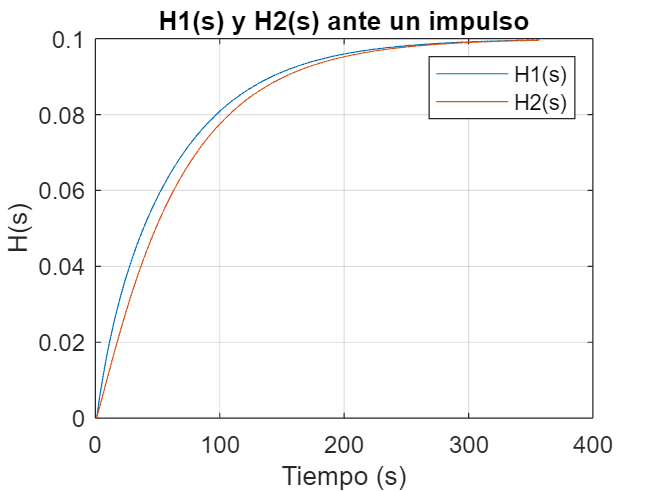

% Gráfico de H1(s) y H2(s) ante un impulso
figure;
plot(step(H));
title("H1(s) y H2(s) ante un impulso");
ylabel("H(s)");
xlabel("Tiempo (s)");
legend("H1(s)", "H2(s)")
grid on;

Y, por último, la respuesta ante un escalón para ambas salidas.

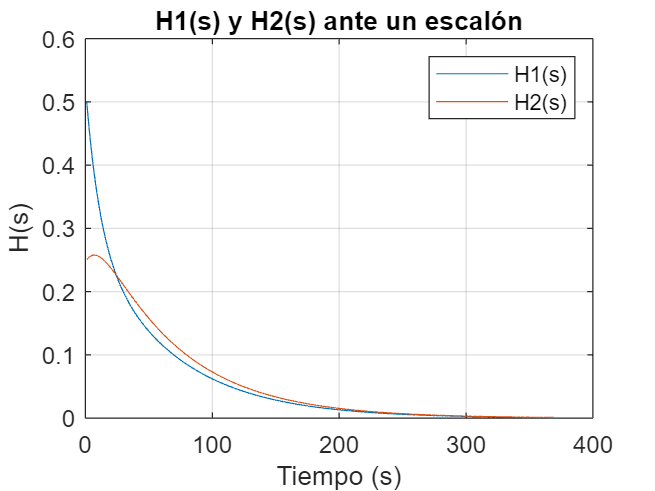

% Gráfico de H1(s) y H2(s) ante un escalón
figure;
plot(impulse(H));
title("H1(s) y H2(s) ante un escalón");
ylabel("H(s)");
xlabel("Tiempo (s)");
legend("H1(s)", "H2(s)")
grid on;